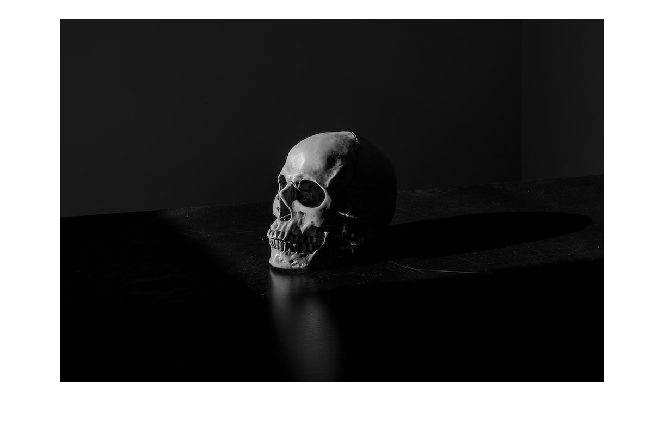

A=rgb2gray(imread("E:\Matlab\assets\darkImage.jpeg"));
[R C]=size(A);  % get the size of A and store it r and c
figure;imshow(A);

% input filter as
k=33

k = 33

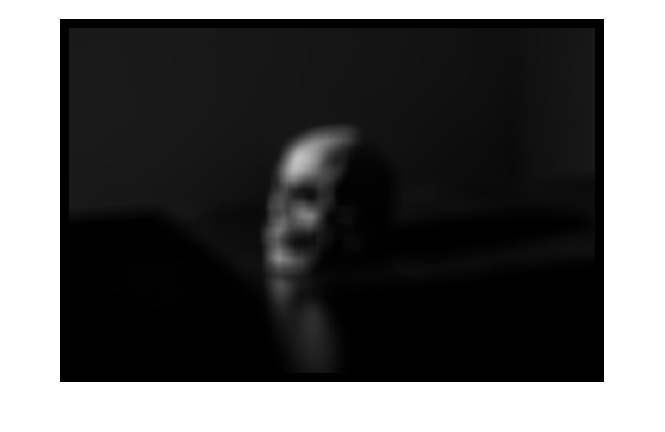

filter=k*k;
init=round(k/2);
termint=(round(k/2)-1);

B=zeros(R,C);
for i=init:1:R-termint
    for j=init:1:C-termint
        myN=A(i-termint:i+termint,j-termint:j+termint);
        myNR=reshape(myN,1,[]);
        myNRS=sum(myNR);
        myValue=myNRS/filter;
        B(i,j)=myValue;
    end
end

figure;imshow(uint8(B));